# 繪圖軟體應用 第6周(10/16)

## 1) 海岸線繪製

[NOAA](https://www.ngdc.noaa.gov/mgg/shorelines/shorelines.html) : [https://www.ngdc.noaa.gov/mgg/shorelines/shorelines.html](https://www.ngdc.noaa.gov/mgg/shorelines/shorelines.html)

clear;clc;clf
load Pacific_coast.dat %載入檔案
whos

  Name                   Size             Bytes  Class     Attributes

  Pacific_coast      14741x2             235856  double              



lons = Pacific_coast(:,1); %取出經度
lats = Pacific_coast(:,2); %取出緯度
plot(lons,lats,'k')
xlabel('Longitude',"FontSize",16,"FontName",'times')
ylabel('Latitude',"FontSize",16,"FontName",'times')
title('The Coastline of the west Pacific','FontName','times')
axis([110 130 15 40])
axis('image') %讓圖形在縮放之後不會變形
text(120,24,'Taiwan','FontSize',13,'FontName','times','Color','r')%在圖中標示台灣
text(115,30,'China','FontSize',14,'FontName','times','Color','r')%在圖中標示中國

%自訂坐標軸區間
get(gca) %get current axes，查詢可調整的東西

                       ALim: [0 1]
                   ALimMode: 'auto'
     ActivePositionProperty: 'outerposition'
                 AlphaScale: 'linear'
                   Alphamap: [1×64 double]
          AmbientLightColor: [1 1 1]
               BeingDeleted: 'off'
                        Box: 'on'
                   BoxStyle: 'back'
                 BusyAction: 'queue'
              ButtonDownFcn: ''
                       CLim: [0 1]
                   CLimMode: 'auto'
             CameraPosition: [120.0207 30.9062 149.8917]
         CameraPositionMode: 'auto'
               CameraTarget: [120.0207 30.9062 0]
           CameraTargetMode: 'auto'
             CameraUpVector: [0 1 0]
         CameraUpVectorMode: 'auto'
            CameraViewAngle: 8.4588
        CameraViewAngleMode: 'auto'
                   Children: [3×1 Graphics]
                   Clipping: 'on'
              ClippingStyle: '3dbox'
                      Color: [1 1 1]
                 ColorOrder: [7×3 double]
   

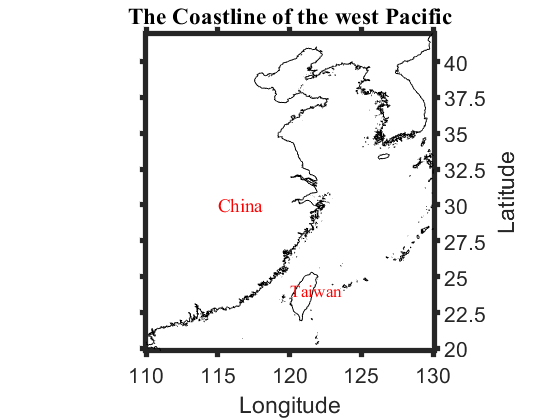

set(gca,'fontsize',16)%坐標軸設定字體大小設定
set(gca,'LineWidth',4)%坐標軸設定粗細
set(gca,'TickDir','out')%設定座標tick的方向向外
set(gca,'XTick',[110:5:130])%改變 X 座標標示 110到130間隔5
set(gca,'YTick',[20:2.5:40])%改變 Y 座標標示 20到40間隔2.5
set(gca,'yAxisLocation','right') %把 Y 軸改到右邊

print('Pcacific_coast_00781035','-djpeg') %存圖

dir  %查詢資料夾裡有哪些檔案


.                            Pacific_coast.dat            gshhg-shp-2.3.7.zip          map_W32.mlx                  map_W71_00781035.png         
..                           Pcacific_coast_00781035.jpg  land_data                    map_W41.mlx                  map_W72_00781035.m           
COPYING.LESSERv3             README.TXT                   land_data.rar                map_W61.mlx                  map_W81.mlx                  
GSHHS_shp                    SHAPEFILES.TXT               map_W21.mlx                  map_W71.mlx                  plot_KEELUNG.dat             
LICENSE.TXT                  WDBII_shp                    map_W31.mlx                  map_W71_00781035.m           plot_KL.m                    



## 2) 改變坐標軸標示為文字

clear;clc;clf
x = linspace(1,12,12);
y = sin(x);
whos

  Name      Size            Bytes  Class     Attributes

  x         1x12               96  double              
  y         1x12               96  double              



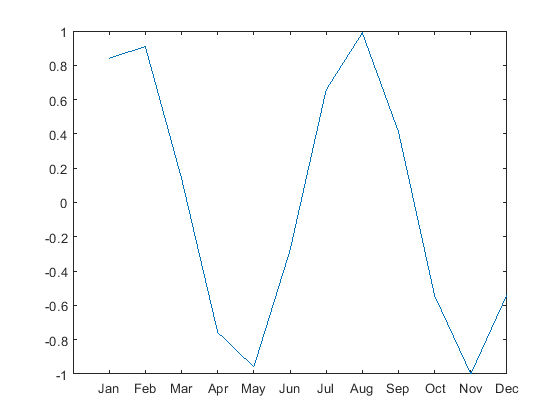

plot(x,y)
set(gca,'XTick',[1:12],'xticklabel',{'Jan';'Feb';'Mar';'Apr';'May';...
    'Jun';'Jul';'Aug';'Sep';'Oct';'Nov';'Dec'})

## 3) 畫圖中之圖

在圖中告訴讀者畫出的圖在哪裡

doc axes

doc axes properties     

clear;clc;clf
load Pacific_coast.dat %載入檔案
whos

  Name                   Size             Bytes  Class     Attributes

  Pacific_coast      14741x2             235856  double              



lons = Pacific_coast(:,1); %取出經度
lats = Pacific_coast(:,2); %取出緯度
plot(lons,lats,'k')
xlabel('Longitude',"FontSize",16,"FontName",'times')
ylabel('Latitude',"FontSize",16,"FontName",'times')
title('The Coastline of the North Taiwan')
axis([121.1 122 24.9 25.5])
% axis('image') %讓圖形在縮放之後不會變形


get(gca); %get current axes，查詢可調整的東西

                       ALim: [0 1]
                   ALimMode: 'auto'
     ActivePositionProperty: 'outerposition'
                 AlphaScale: 'linear'
                   Alphamap: [1×64 double]
          AmbientLightColor: [1 1 1]
               BeingDeleted: 'off'
                        Box: 'on'
                   BoxStyle: 'back'
                 BusyAction: 'queue'
              ButtonDownFcn: ''
                       CLim: [0 1]
                   CLimMode: 'auto'
             CameraPosition: [121.5500 25.2000 17.3205]
         CameraPositionMode: 'auto'
               CameraTarget: [121.5500 25.2000 0]
           CameraTargetMode: 'auto'
             CameraUpVector: [0 1 0]
         CameraUpVectorMode: 'auto'
            CameraViewAngle: 6.6086
        CameraViewAngleMode: 'auto'
                   Children: [1×1 Line]
                   Clipping: 'on'
              ClippingStyle: '3dbox'
                      Color: [1 1 1]
                 ColorOrder: [7×3 double]
        

set(gca,'fontsize',16,'LineWidth',4,'TickDir','out')
set(gca,'XTick',[110:2.5:130],'YTick',[20:0.25:25.5],'yAxisLocation','left')

%% 畫圖中圖
get(gca,'position') % 左 底部 寬度 高度 

ans =     0.1716    0.1100    0.7334    0.8034


axes('position',[0.085 0.6 0.4 0.3])

hold on 

load Pacific_coast.dat %載入檔案
lons = Pacific_coast(:,1); %取出經度
lats = Pacific_coast(:,2); %取出緯度
plot(lons,lats,'k')
% xlabel('Longitude',"FontSize",16,"FontName",'times')
% ylabel('Latitude',"FontSize",16,"FontName",'times')
% title('The Coastline of the west Pacific')
axis([110 130 15 40])
axis('image') %讓圖形在縮放之後不會變形
text(120,24,'Taiwan','FontSize',13,'FontName','times','Color','r','rotation',45)%在圖中標示台灣

%自訂坐標軸區間
get(gca) %get current axes，查詢可調整的東西

                       ALim: [0 1]
                   ALimMode: 'auto'
     ActivePositionProperty: 'position'
                 AlphaScale: 'linear'
                   Alphamap: [1×64 double]
          AmbientLightColor: [1 1 1]
               BeingDeleted: 'off'
                        Box: 'off'
                   BoxStyle: 'back'
                 BusyAction: 'queue'
              ButtonDownFcn: ''
                       CLim: [0 1]
                   CLimMode: 'auto'
             CameraPosition: [120.0207 30.9062 149.8917]
         CameraPositionMode: 'auto'
               CameraTarget: [120.0207 30.9062 0]
           CameraTargetMode: 'auto'
             CameraUpVector: [0 1 0]
         CameraUpVectorMode: 'auto'
            CameraViewAngle: 8.4588
        CameraViewAngleMode: 'auto'
                   Children: [2×1 Graphics]
                   Clipping: 'on'
              ClippingStyle: '3dbox'
                      Color: [1 1 1]
                 ColorOrder: [7×3 double]
       

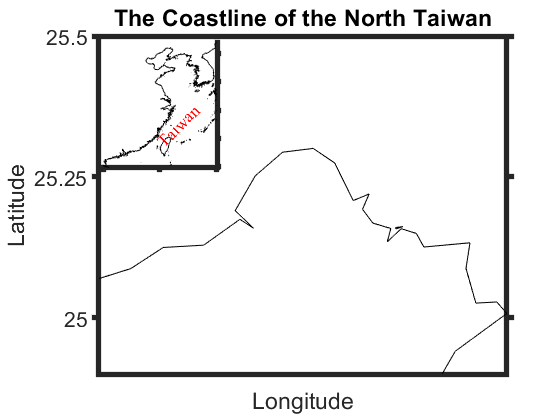

set(gca,'fontsize',16)%坐標軸設定字體大小設定
set(gca,'fontname','times')
set(gca,'LineWidth',4)%坐標軸設定粗細
set(gca,'TickDir','out')%設定座標tick的方向向外
set(gca,'XTick',[110:10:130])%改變 X 座標標示 110到130間隔5
set(gca,'YTick',[20:5:40])%改變 Y 座標標示 20到40間隔2.5
set(gca,'yAxisLocation','right')
set(gca,'xticklabels',{},'yticklabels',{})
print('coast_NorthTaiwan','-djpeg') %存圖

## 4) 